# Visualization of spectra and pseudospectra

## Problem.

The eigenvalues of *Toeplitz* matrices, which have a constant value on each diagonal, have beautiful connections to complex analysis. Define six $64 \times 64$ Toeplitz matrices using

z = zeros(1,60);
A{1} = toeplitz( [0,0,0,0,z], [0,1,1,0,z] );
A{2} = toeplitz( [0,1,0,0,z], [0,2i,0,0,z] );
A{3} = toeplitz( [0,2i,0,0,z], [0,0,1,0.7,z] );
A{4} = toeplitz( [0,0,1,0,z], [0,1,0,0,z] );
A{5} = toeplitz( [0,1,2,3,z], [0,-1,-2,0,z] );
A{6} = toeplitz( [0,0,-4,-2i,z], [0,2i,-1,2,z] );

(The variable `A` constructed hereinabove is a *cell array*. Type `doc cell` to learn more about this.) For each of the six matrices, do the following.

(a) Plot the eigenvalues of `A{#}` as red dots in the complex plane. (Set `'MarkerSize'` to be 3.)

(b) Let $E$ and $F$ be $64 \times 64$ random matrices generated by `randn`. On top of the plot from part (a), plot the eigenvalues of the matrix $A + \varepsilon E + i \varepsilon F$ as blue dots, where $\varepsilon = 10^{-3}$. (Set `'MarkerSize'` to be 1.)

(c) Repeat part (b) 49 more times (generating a single plot).

Arrange all six plots in a $3 \times 2$ grid using `subplot`. Make sure all figures are drawn in 1:1 aspect ratio.

## **Solution.**

Before we start solving the problem, let me briefly show you how `toeplitz` works. Take a look at the following simpler construction.

toeplitz([0,-1,-2,-3,-4],[0,1,2,3,4])

ans =      0     1     2     3     4
    -1     0     1     2     3
    -2    -1     0     1     2
    -3    -2    -1     0     1
    -4    -3    -2    -1     0


This matrix has a constant value on each diagonal. Precisely, on the subdiagonals, starting from the main diagonal, we have

- main diagonal: 0

- 1st subdiagonal: -1

- 2nd subdiagonal: -2

- 3rd subdiagonal: -3

- 4th subdiagonal: -4

Likewise, on the superdiagonals, starting from the main diagonal, we have

- main diagonal: 0

- 1st superdiagonal: 1

- 2nd superdiagonal: 2

- 3rd superdiagonal: 3

- 4th superdiagonal: 4

These constant values on the diagonals are fed into `toeplitz` in the form of two vectors, one after another, and their first elements must agree. This seemingly simple structure enjoys many surprising analytical properties, and conversely, Toeplitz matrices appear here and there in mathematical modelling. Let's me just say this much and get back to the main problem.

Now let's play with one of the 6 matrices and build up from there.

X = A{1};
[~, D] = eig(X);

Note that I used a placeholder `[~, D] `since we do not need eigenvectors. The sole output `D` must be a diagonal matrix and its diagonal entries are eigenvalues of `X.`

diag(D)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


But wait, all its eigenvalues are 0. In other words, there is only one eigenvalue $\lambda = 0$ whose algebraic multiplicity is 64! Does it make sense? Let's peak into $X$:

X(1:10, 1:10)

ans =      0     1     1     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0


As we see, all diagonals are zeros and it is not difficult to see that the characteristic polynomial of $X$ is simply $\det(X - \lambda I) = \lambda^{64}$.

Alright, so if you plot all eigenvalues in the complex plane, you must see a single dot at the origin.

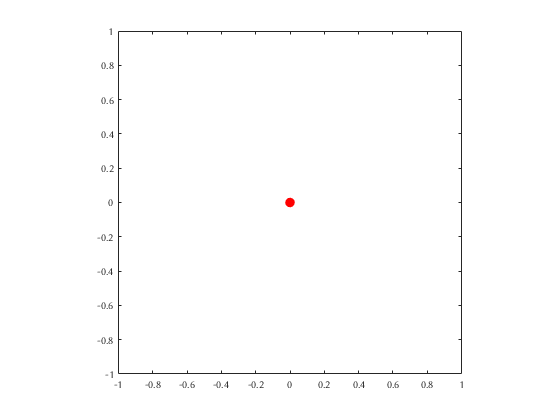

clf
plot(real(diag(D)), imag(diag(D)), 'r.', 'MarkerSize', 30)
axis image

Now, if we perturb this matrix $X$ by a random complex matrix, all these 64 eigenvalues concentrated at the origin must be scattered. Let's see how these eigenvalues are perturbed in the complex plane.

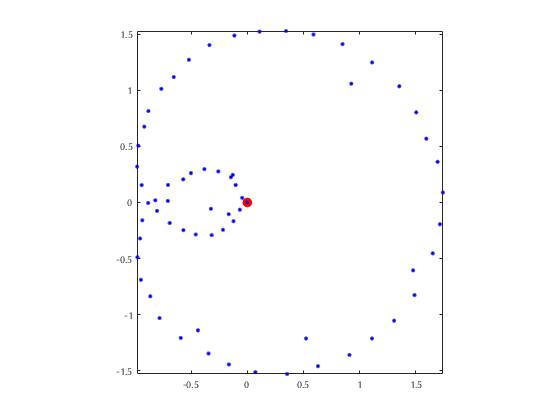

E = randn(64);
F = randn(64);
[~, Dp] = eig(X+1e-3*(E+1i*F));
hold on
plot(real(Dp), imag(Dp), 'b.', 'MarkerSize', 10)
axis image

It appears that the eigenvalues are getting spread out in some pattern. Run this block multiple times and see that it traces out a Limacon with a loop. 

Now that we have a clear idea of what the problem is asking us to do, let's write a neat script that goes through all parts with all six matrices and produces a nice plot. The following block may take a couple minutes to run; stay patient.

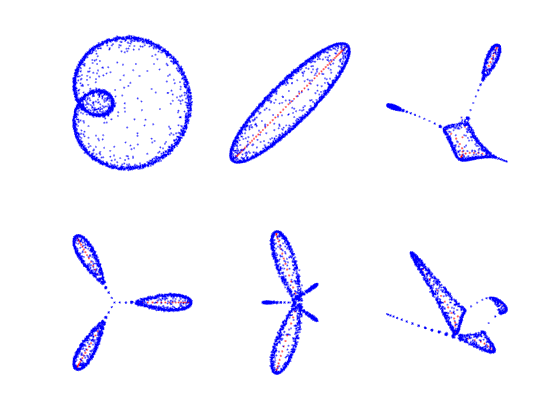

clf
for j = 1:length(A)
    X = A{j};
    [~,D] = eig(X);
    subplot(2,3,j)
    plot(real(D), imag(D), 'r.', 'MarkerSize', 3)
    hold on
    for i = 1:50
        E = randn(64);
        F = randn(64);
        [Vp, Dp] = eig(X+1e-3*E+1i*1e-3*F);
        plot(real(Dp), imag(Dp), 'b.', 'MarkerSize', 1)
    end
    axis image, axis off
end